# Reunião de orientação — 12/06/2026

**Gêmeo digital de fidelidade observacional do robô SSL — do zero ao estado atual.** Roteiro executável: cada seção abaixo é um "slide" com dados, figura e takeaway. REGRA DURA: nenhuma re-simulação — todo número vem de artefatos versionados em `results/` e `models/` (CHANGELOG com commit, θ e seed de cada um). Os únicos cálculos ao vivo são medianas de CSVs, a demo das duas âncoras numa trajetória salva, o dead-reckoning analítico de 1 evento e a aritmética do teto de ruído (todos < 10 s).

RERUN = false;  %#ok<NASGU> % nenhuma re-simulação neste roteiro
t_roteiro = tic;
if exist('bootstrap_paths','file') ~= 2
    addpath(fullfile(fileparts(mfilename('fullpath')), '..', 'scripts'));
end
repo = bootstrap_paths();

Raiz do repo: C:\Users\victo\Documents\digitaltwin
pwd ajustado para a raiz.


addpath(fullfile(repo, 'automation'));
art = resolve_artefatos(repo);   % erra listando o que faltar — nunca recalcula

## 1. O problema e o modelo

Tese: gêmeo digital com **fidelidade observacional comportamental** do robô SSL omnidirecional (4 rodas, versão 2025). Contribuição central: identificação grey-box POR GRAU DE LIBERDADE, $G_i(s) = K_i e^{-T_{d,i} s} / (\tau_i s + 1)$ para $i \in \{v_x, v_y, \omega\}$ → 9 parâmetros (ordem fixa no SLDD). Por que 1ª ordem + atraso? A única observação disponível é POSE da visão a 60 Hz (malha fechada de competição): derivar velocidade amplifica ruído, então só estruturas de baixa ordem são identificáveis — e o atraso Td captura a latência física rádio+firmware, que dados de pose-only não deixam separar de dinâmica rápida. Critérios de aceite (CLAUDE.md): fit_val ≥ 60%, K_w ∈ [0.5, 2], τ_w ∈ [0.02, 0.5] s, Td_w ≤ 0.15 s.

th_pl = load_theta_mat(art.ini_mat);                 % procest placeholder

  → usando variável "theta0" de C:\Users\victo\Documents\digitaltwin\results\sysid_initial.mat


cand  = load(art.cand_mat);                          % candidato ω (NÃO promovido)
th_ca = cand.theta0;
nomes = {'K_vx';'tau_vx';'Td_vx';'K_vy';'tau_vy';'Td_vy';'K_w';'tau_w';'Td_w'};
T_theta = table(cellfun(@(f) th_pl.(f), nomes), cellfun(@(f) th_ca.(f), nomes), ...
    'RowNames', nomes, 'VariableNames', ...
    {'procest_placeholder', 'procest_w_cand_NAO_promovido'});
disp(T_theta)

              procest_placeholder    procest_w_cand_NAO_promovido
              ___________________    ____________________________

    K_vx            0.98859                     0.98859          
    tau_vx          0.12817                     0.12817          
    Td_vx           0.17075                     0.17075          
    K_vy             0.9493                      0.9493          
    tau_vy          0.24158                     0.24158          
    Td_vy           0.10445                     0.10445          
    K_w                   1                      1.3533          
    tau_w               0.1                    0.035405          
    Td_w                  0                      0.1058          



fprintf(['TAKEAWAY 1: vx/vy identificados por procest; em ω o placeholder usa ' ...
    'K=1, τ=0.1 (chute) e o candidato identificado NÃO foi promovido (seção 6).\n']);

TAKEAWAY 1: vx/vy identificados por procest; em ω o placeholder usa K=1, τ=0.1 (chute) e o candidato identificado NÃO foi promovido (seção 6).


## 2. Os dados — 46 splits de logs de competição

1 log de competição (2026-05-18), 4 labels de movimento, 46 eventos. Cada evento tem comandos de corpo (move_vx/vy/w) e pose da visão (mm/rad). A auditoria de grade (results/grid_audit) mostrou que a grade temporal dos comandos é IRREGULAR em 46/46 eventos (razão p90/p10 dos dT > 3): os labels de movimento logam em rajada (mediana dT ≈ 2 ms), shoot_to_goal a ≈ 20 ms. Isso invalidava qualquer janela definida em nº de amostras.

Tg = readtable(art.grid_csv, 'Delimiter', ',');
okg = strcmp(Tg.status, 'ok');
S2 = groupsummary(Tg(okg,:), 'label', {'sum','median'}, ...
    {'dur_s', 'dT_mediana_ms', 'irregular'});
S2 = S2(:, {'label','GroupCount','sum_dur_s','median_dT_mediana_ms','sum_irregular'});
S2.Properties.VariableNames = {'label','n_eventos','dur_total_s', ...
    'dT_mediano_ms','n_irregulares'};
disp(S2)

          label          n_eventos    dur_total_s    dT_mediano_ms    n_irregulares
    _________________    _________    ___________    _____________    _____________

    {'front_to_back'}        4          32.877          1.9431              4      
    {'shoot_to_goal'}       18          125.88          20.048             18      
    {'side_to_side' }       13          120.75          2.0014             13      
    {'square'       }       11          99.449          1.8391             11      



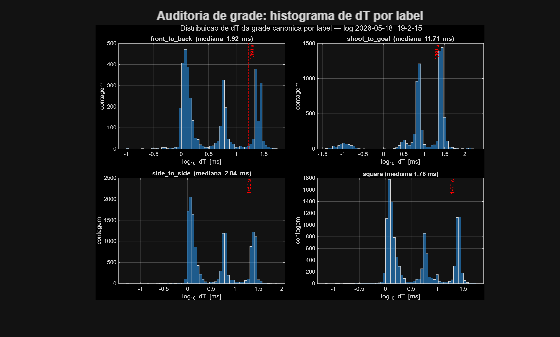

embed_png(art.png_grid, 'Auditoria de grade: histograma de dT por label');

fprintf(['TAKEAWAY 2: %d eventos / %.0f s de dados; grade irregular em todos ' ...
    '→ janelas da métrica passaram a ser definidas POR TEMPO.\n'], ...
    sum(S2.n_eventos), sum(S2.dur_total_s));

TAKEAWAY 2: 46 eventos / 379 s de dados; grade irregular em todos → janelas da métrica passaram a ser definidas POR TEMPO.


## 3. A régua — como medir um gêmeo free-run

O gêmeo roda em **free-run** (replay dos comandos do log, sem reinjetar pose medida — o oposto de **teacher forcing**). O erro de posição então ACUMULA; a métrica honesta re-ancora a simulação no truth no início de cada janela de h segundos (overlap 0.5) e mede o RMSE só dentro da janela. Duas âncoras: (a) TRANSLAÇÃO — rebase x,y; (b) POSE SE(2) — rebase x,y,θ (rotação rígida sim→truth em t0, com θ truth filtrado por mediana móvel de 0.2 s — visão tem outliers de heading). Demo ao vivo numa trajetória SALVA da campanha (shoot_to_goal_05_02, procest_placeholder — o mesmo evento reaparece na seção 8):

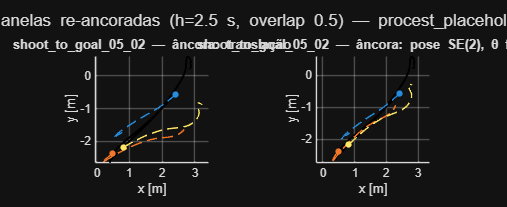

Straj = load(art.traj_mat);  traj = Straj.traj;
tr3 = traj(strcmp({traj.event}, 'shoot_to_goal_05_02') & ...
           strcmp({traj.theta}, 'procest_placeholder'));
demo_duas_ancoras(tr3, 2.5, 0.5);

r_tr3  = rmse_pos_rebased(tr3.t, tr3.x_sim, tr3.y_sim, ...
    tr3.x_truth, tr3.y_truth, 2.5, 0.5);
r_se23 = rmse_pos_rebased_se2(tr3.t, tr3.x_sim, tr3.y_sim, tr3.th_sim, ...
    tr3.x_truth, tr3.y_truth, tr3.th_truth, 2.5, 0.5);
fprintf(['TAKEAWAY 3: mesma trajetória, duas réguas — trans %.3f m vs SE(2) ' ...
    '%.3f m (h=2.5 s). A diferença é o erro de heading acumulado ATÉ a ' ...
    'âncora, não a dinâmica dentro da janela.\n'], r_tr3, r_se23);

TAKEAWAY 3: mesma trajetória, duas réguas — trans 0.874 m vs SE(2) 0.622 m (h=2.5 s). A diferença é o erro de heading acumulado ATÉ a âncora, não a dinâmica dentro da janela.


## 4. Simulador verificado — o gêmeo é totalmente explicável

Antes de discutir números, a cadeia Simulink (TransferFcn → TransportDelay → cinemática de rodas → rotação p/ global → integradores) foi RECONCILIADA com um modelo analítico exato (FOH + Euler 60 Hz): max|Δx| = 4.6 mm, max|Δy| = 5.7 mm, max|Δθ| = 0.0009 rad no square_01_01 (fonte: CHANGELOG 2026-06-11 17:25, commit eb97620). Abaixo, ao vivo: dead-reckoning analítico do square_01_01 sobreposto às trajetórias salvas — bate exatamente com a trajetória ideal salva da campanha (mesma função, mesmos dados), evidência de reprodutibilidade dos artefatos.

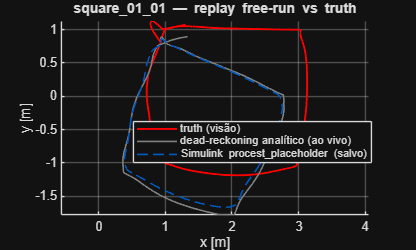

canon4 = canonical_split(fullfile(repo, 'data', 'extracted', ...
    '2026-05-18_19-2-15', 'splits', 'square', 'square_01_01', 'commands.parquet'));
s4 = load_split(canon4);
[x4, y4] = ideal_deadreckoning(s4);              % cálculo ao vivo permitido
tr4i = traj(strcmp({traj.event},'square_01_01') & strcmp({traj.theta},'ideal_analytic'));
tr4p = traj(strcmp({traj.event},'square_01_01') & strcmp({traj.theta},'procest_placeholder'));
d4 = max(hypot(x4 - tr4i.x_sim, y4 - tr4i.y_sim));
assert(d4 < 1e-6, 'dead-reckoning ao vivo difere da trajetória salva (%.3g m)', d4);
figure('Name','S4 simulador verificado');
hold on; axis equal; grid on;
plot(tr4i.x_truth, tr4i.y_truth, 'r-', 'LineWidth', 1.4);
plot(x4, y4, '-', 'Color', [.5 .5 .5], 'LineWidth', 1.2);
plot(tr4p.x_sim, tr4p.y_sim, '--', 'Color', [0 .35 .75], 'LineWidth', 1.2);
legend({'truth (visão)', 'dead-reckoning analítico (ao vivo)', ...
    'Simulink procest\_placeholder (salvo)'}, 'Location', 'best');
title('square\_01\_01 — replay free-run vs truth');
xlabel('x [m]'); ylabel('y [m]');

fprintf(['TAKEAWAY 4: reconciliação fecha em milímetros e o analítico ao vivo ' ...
    'reproduz a trajetória salva com max|Δ| = %.2g m → desvios do truth são ' ...
    'FENÔMENO, não bug do simulador.\n'], d4);

TAKEAWAY 4: reconciliação fecha em milímetros e o analítico ao vivo reproduz a trajetória salva com max|Δ| = 0 m → desvios do truth são FENÔMENO, não bug do simulador.


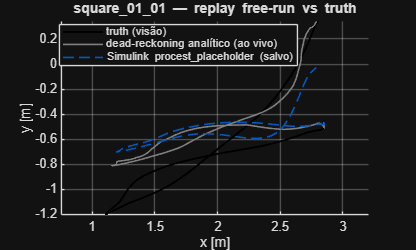

canon4 = canonical_split(fullfile(repo, 'data', 'extracted', ...
    '2026-05-18_19-2-15', 'splits', 'shoot_to_goal', 'shoot_to_goal_08_01', 'commands.parquet'));
s4 = load_split(canon4);
[x4, y4] = ideal_deadreckoning(s4);              % cálculo ao vivo permitido
tr4i = traj(strcmp({traj.event},'shoot_to_goal_08_01') & strcmp({traj.theta},'ideal_analytic'));
tr4p = traj(strcmp({traj.event},'shoot_to_goal_08_01') & strcmp({traj.theta},'procest_placeholder'));
d4 = max(hypot(x4 - tr4i.x_sim, y4 - tr4i.y_sim));
assert(d4 < 1e-6, 'dead-reckoning ao vivo difere da trajetória salva (%.3g m)', d4);
figure('Name','S4 simulador verificado');
hold on; axis equal; grid on;
plot(tr4i.x_truth, tr4i.y_truth, 'k-', 'LineWidth', 1.4);
plot(x4, y4, '-', 'Color', [.5 .5 .5], 'LineWidth', 1.2);
plot(tr4p.x_sim, tr4p.y_sim, '--', 'Color', [0 .35 .75], 'LineWidth', 1.2);
legend({'truth (visão)', 'dead-reckoning analítico (ao vivo)', ...
    'Simulink procest\_placeholder (salvo)'}, 'Location', 'best');
title('square\_01\_01 — replay free-run vs truth');
xlabel('x [m]'); ylabel('y [m]');

fprintf(['TAKEAWAY 4: reconciliação fecha em milímetros e o analítico ao vivo ' ...
    'reproduz a trajetória salva com max|Δ| = %.2g m → desvios do truth são ' ...
    'FENÔMENO, não bug do simulador.\n'], d4);

TAKEAWAY 4: reconciliação fecha em milímetros e o analítico ao vivo reproduz a trajetória salva com max|Δ| = 0 m → desvios do truth são FENÔMENO, não bug do simulador.


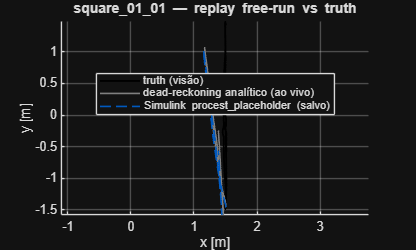

canon4 = canonical_split(fullfile(repo, 'data', 'extracted', ...
    '2026-05-18_19-2-15', 'splits', 'front_to_back', 'front_to_back_01_01', 'commands.parquet'));
s4 = load_split(canon4);
[x4, y4] = ideal_deadreckoning(s4);              % cálculo ao vivo permitido
tr4i = traj(strcmp({traj.event},'front_to_back_01_01') & strcmp({traj.theta},'ideal_analytic'));
tr4p = traj(strcmp({traj.event},'front_to_back_01_01') & strcmp({traj.theta},'procest_placeholder'));
d4 = max(hypot(x4 - tr4i.x_sim, y4 - tr4i.y_sim));
assert(d4 < 1e-6, 'dead-reckoning ao vivo difere da trajetória salva (%.3g m)', d4);
figure('Name','S4 simulador verificado');
hold on; axis equal; grid on;
plot(tr4i.x_truth, tr4i.y_truth, 'k-', 'LineWidth', 1.4);
plot(x4, y4, '-', 'Color', [.5 .5 .5], 'LineWidth', 1.2);
plot(tr4p.x_sim, tr4p.y_sim, '--', 'Color', [0 .35 .75], 'LineWidth', 1.2);
legend({'truth (visão)', 'dead-reckoning analítico (ao vivo)', ...
    'Simulink procest\_placeholder (salvo)'}, 'Location', 'best');
title('square\_01\_01 — replay free-run vs truth');
xlabel('x [m]'); ylabel('y [m]');

fprintf(['TAKEAWAY 4: reconciliação fecha em milímetros e o analítico ao vivo ' ...
    'reproduz a trajetória salva com max|Δ| = %.2g m → desvios do truth são ' ...
    'FENÔMENO, não bug do simulador.\n'], d4);

TAKEAWAY 4: reconciliação fecha em milímetros e o analítico ao vivo reproduz a trajetória salva com max|Δ| = 0 m → desvios do truth são FENÔMENO, não bug do simulador.


## 5. Os 4 defeitos de validade encontrados (e corrigidos)

O número "RMSE do gêmeo" mudou 7× de tamanho ao longo da semana — cada mudança foi um defeito de VALIDADE do experimento, não do robô: (1) ICs dos integradores hardcoded (pose inicial errada); (2) zonas mortas na cadeia de rodas engoliam 84% do cmd_vw do square (fonte: CHANGELOG 2026-06-11 17:25) — θ(t) ficava congelado; (3) janelas da métrica em nº de amostras colapsavam p/ janela única em 34/46 eventos (grade irregular, seção 2); (4) âncora SE(2) com θ truth CRU — um outlier de visão em t0 pode girar a janela inteira (fix de ROBUSTEZ: mediana móvel 0.2 s; efeito nas medianas < 2%; honestidade: no evento motivador 12_01 o SE(2) > trans PERSISTE com filtro — não era outlier, é rotação real na janela).

tm_pre  = readtable(art.tm_pre_csv, 'Delimiter', ',');  % 0728 (ICs hardcoded)
tm_pos  = readtable(art.tm_pos_csv, 'Delimiter', ',');  % 0852 (ICs corrigidas)
pre6    = readtable(art.pre_csv, 'Delimiter', ',');       % eval 6 eventos, janela amostral
pos6    = readtable(art.pos_csv, 'Delimiter', ',');       % eval 6 eventos, janela por tempo
Th      = readtable(art.horiz_csv, 'Delimiter', ',');     % multi-horizonte, âncora filtrada
v1 = tm_pre.rmse_pos_m(strcmp(tm_pre.theta, 'procest'));
v2 = tm_pos.rmse_pos_m(strcmp(tm_pos.theta, 'procest'));
v3a = median(pre6.rmse_trans_m(strcmp(pre6.theta, 'procest_placeholder')));
v3b = median(pos6.rmse_trans_m(strcmp(pos6.theta, 'procest_placeholder')));
% defeito 4: mediana SE(2) do ideal nos MESMOS 6 eventos, âncora crua (pos6)
% vs filtrada (horizons h=2.5 restrito a esses eventos)
m6h = strcmp(Th.theta, 'ideal_analytic') & Th.horizonte_s == 2.5 & ...
    ismember(Th.event, pos6.event);
v4a = median(pos6.rmse_se2_m(strcmp(pos6.theta, 'ideal_analytic')));
v4b = median(Th.rmse_se2_m(m6h));
T_defeitos = table( ...
    {'ICs hardcoded (1.8039/0/0)'; 'zonas mortas das rodas'; ...
     'janela em nº de amostras'; 'âncora SE(2) com θ cru'}, ...
    {'dbf6130'; 'eb97620'; '615398c'; '8350336'}, ...
    [v1; NaN; v3a; v4a], [v2; NaN; v3b; v4b], ...
    {'square_01_01, procest, h=2.5 (tabela_mestra 0728→0852)'; ...
     'sem nº único: 84% do cmd_vw zerado → reconciliação mm (CHANGELOG 17:25)'; ...
     'mediana 6 eventos, placeholder, trans (eval 2202→2236)'; ...
     'mediana 6 eventos, ideal, SE(2) cru→filtrado (eval 2236→horizons 2325)'}, ...
    'VariableNames', {'defeito','commit_fix','rmse_antes_m','rmse_depois_m','medido_em'});
disp(T_defeitos)

               defeito                commit_fix     rmse_antes_m    rmse_depois_m                                     medido_em                                 
    ______________________________    ___________    ____________    _____________    ___________________________________________________________________________

    {'ICs hardcoded (1.8039/0/0)'}    {'dbf6130'}       2.2966          0.40528       {'square_01_01, procest, h=2.5 (tabela_mestra 0728→0852)'                 }
    {'zonas mortas das rodas'    }    {'eb97620'}          NaN              NaN       {'sem nº único: 84% do cmd_vw zerado → reconciliação mm (CHANGELOG 17:25)'}
    {'janela em nº de amostras'  }    {'615398c'}      0.54813          0.42394       {'mediana 6 eventos, placeholder, trans (eval 2202→2236)'                 }
    {'âncora SE(2) 

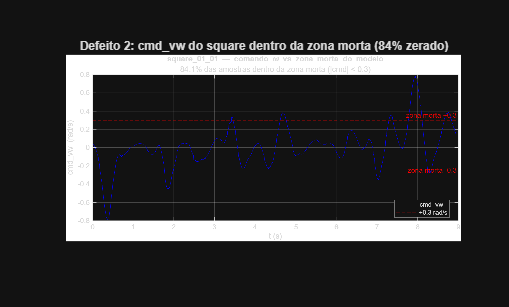

embed_png(art.png_dz, 'Defeito 2: cmd_vw do square dentro da zona morta (84% zerado)');

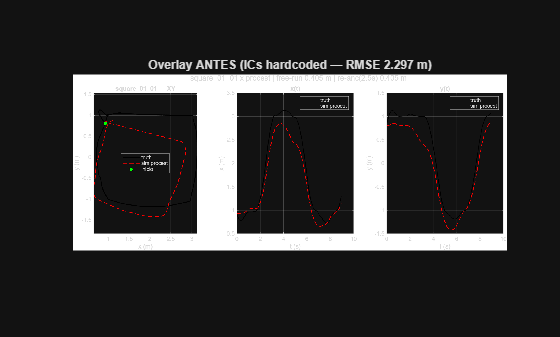

embed_png(art.png_ov_antes, 'Overlay ANTES (ICs hardcoded — RMSE 2.297 m)');

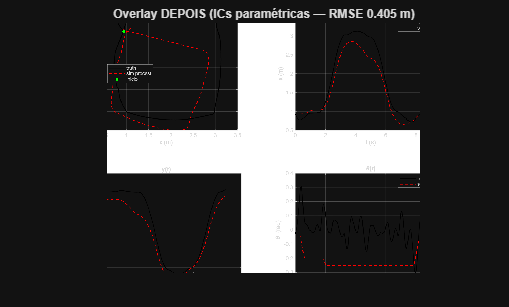

embed_png(art.png_ov_depois, 'Overlay DEPOIS (ICs paramétricas — RMSE 0.405 m)');

fprintf(['TAKEAWAY 5: 2.30 → 0.405 → 0.65 → 0.32–0.34 m: cada salto foi um ' ...
    'defeito de validade corrigido e regredido; a régua atual está defensável.\n']);

TAKEAWAY 5: 2.30 → 0.405 → 0.65 → 0.32–0.34 m: cada salto foi um defeito de validade corrigido e regredido; a régua atual está defensável.


## 6. Identificação ω — candidato dentro dos bounds, fit limitado por ruído

ω é o DOF crítico (heading governa a rotação dos comandos de corpo). Seleção por excitação nos 18 eventos de shoot_to_goal; 14 qualificados (w_ativo ≥ 1 s, std ≥ 0.7 rad/s), 9 treino / 5 hold-out (seed 42). procest P1D sobre iddata em grade UNIFORME Ts=1/60 (regrade — a grade irregular da seção 2 não afeta a identificação).

E = readtable(art.exc_csv, 'Delimiter', ',');
qual = E.w_ativo_s >= 1 & E.std_move_w >= 0.7;
T_exc = sortrows(E(:, {'event','duration_s','std_move_w','w_ativo_s'}), ...
    'w_ativo_s', 'descend');
disp(T_exc)

             event             duration_s    std_move_w    w_ativo_s
    _______________________    __________    __________    _________

    {'shoot_to_goal_04_01'}      8.7851        1.0715        3.5235 
    {'shoot_to_goal_12_01'}      9.5242        1.2502        3.3135 
    {'shoot_to_goal_14_02'}      7.0758       0.89741        2.4931 
    {'shoot_to_goal_02_01'}      4.3596        1.4744        2.3402 
    {'shoot_to_goal_05_02'}      5.7983       0.73347        2.2176 
    {'shoot_to_goal_11_01'}      8.6392       0.95384        2.1457 
    {'shoot_to_goal_09_01'}      8.3201       0.92756        2.0765 
    {'shoot_to_goal_08_01'}      4.7977       0.76284        1.9675 
    {'shoot_to_goal_10_01'}      5.4664       0.72988        1.8811 
    {'shoot_to_goal_14_01'}      7.0754        1.0189         1.771 
    {'shoot_to_goal_11_02'}       8

fprintf('Eventos: %d | qualificados: %d | excitação ω total: %.1f s (qualificados: %.1f s)\n', ...
    height(E), nnz(qual), sum(E.w_ativo_s), sum(E.w_ativo_s(qual)));

Eventos: 18 | qualificados: 14 | excitação ω total: 32.1 s (qualificados: 29.0 s)


fprintf('θ_w candidato (NÃO promovido): K=%.3f, τ=%.1f ms, Td=%.1f ms | fit hold-out médio %.1f%% (critério: ≥60%%)\n', ...
    cand.theta_w.K_w, 1e3*cand.theta_w.tau_w, 1e3*cand.theta_w.Td_w, ...
    mean(cand.report.fit_val, 'omitnan'));

θ_w candidato (NÃO promovido): K=1.353, τ=35.4 ms, Td=105.8 ms | fit hold-out médio 52.6% (critério: ≥60%)


% --- teto de ruído (aritmética ao vivo) ---
% ω medido = derivada do heading da visão: σ_ω ≈ σ_θ·√2·fs. Com sgolay de
% 5 amostras, σ_eff ≈ σ_ω/√5. Escala do sinal: mediana do std(cmd_vw) dos
% qualificados. Teto de fit NRMSE ≈ 100·(1 − σ_eff/σ_sinal).
sigma_th = [5 15] * 1e-3;             % ruído de heading da visão [rad]
fs = 60;
sigma_w   = sigma_th * sqrt(2) * fs;  % ruído na derivada [rad/s]
sigma_eff = sigma_w / sqrt(5);        % após sgolay (janela 5)
sigma_sig = median(E.std_move_w(qual));
fit_teto  = 100 * (1 - sigma_eff / sigma_sig);
fprintf(['Teto de ruído: σ_θ ∈ [%g, %g] mrad → σ_ω ∈ [%.2f, %.2f] rad/s ' ...
    '(σ_eff [%.2f, %.2f] pós-sgolay) vs sinal %.2f rad/s → fit máximo ≈ ' ...
    '[%.0f%%, %.0f%%].\n'], 1e3*sigma_th(1), 1e3*sigma_th(2), sigma_w(1), ...
    sigma_w(2), sigma_eff(1), sigma_eff(2), sigma_sig, fit_teto(2), fit_teto(1));

Teto de ruído: σ_θ ∈ [5, 15] mrad → σ_ω ∈ [0.42, 1.27] rad/s (σ_eff [0.19, 0.57] pós-sgolay) vs sinal 0.94 rad/s → fit máximo ≈ [39%, 80%].


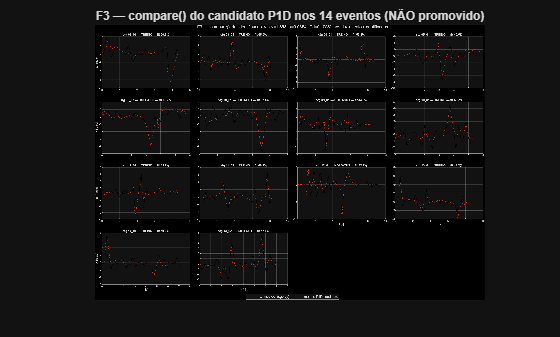

embed_png(art.png_f3, 'F3 — compare() do candidato P1D nos 14 eventos (NÃO promovido)');

fprintf(['TAKEAWAY 6: o fit de 52.6%% está DENTRO da faixa explicável por ' ...
    'ruído de medição — o gargalo é a qualidade da observação (pose-only ' ...
    '60 Hz), não necessariamente o modelo. Td=105.8 ms é fisicamente ' ...
    'plausível (latência rádio+firmware).\n']);

TAKEAWAY 6: o fit de 52.6% está DENTRO da faixa explicável por ruído de medição — o gargalo é a qualidade da observação (pose-only 60 Hz), não necessariamente o modelo. Td=105.8 ms é fisicamente plausível (latência rádio+firmware).


## 7. Campanha completa — 3 modelos × 46 cenários, duas métricas

Tudo da campanha salva (commit 210c70f, seed 42): trajetórias em traj_eval_campaign, métricas recomputáveis dos CSVs. Medianas ao vivo:

Tc = readtable(art.camp_csv, 'Delimiter', ',');
okc = strcmp(Tc.status, 'ok');
M_label = groupsummary(Tc(okc,:), {'label','theta'}, 'median', ...
    {'rmse_trans_m','rmse_se2_m'});
disp(M_label)

          label                   theta             GroupCount    median_rmse_trans_m    median_rmse_se2_m
    _________________    _______________________    __________    ___________________    _________________

    {'front_to_back'}    {'ideal_analytic'     }         4              0.35331               0.27224     
    {'front_to_back'}    {'procest_placeholder'}         4              0.37856                0.2941     
    {'front_to_back'}    {'procest_w_cand'     }         4              0.43728               0.31433     
    {'shoot_to_goal'}    {'ideal_analytic'     }        18              0.38133               0.40574     
    {'shoot_to_goal'}    {'procest_placeholder'}        18              0.42038                0.3588     
    {'shoot_to_goal'}    {'procest_w_cand'     }        18              0.48665 

Mh = readtable(art.horiz_med_csv, 'Delimiter', ',');
Mg = Mh(strcmp(Mh.label, 'global'), :);
T_h_trans = unstack(Mg(:, {'theta','horizonte_s','median_rmse_trans_m'}), ...
    'median_rmse_trans_m', 'horizonte_s', 'VariableNamingRule', 'preserve');
T_h_se2 = unstack(Mg(:, {'theta','horizonte_s','median_rmse_se2_m'}), ...
    'median_rmse_se2_m', 'horizonte_s', 'VariableNamingRule', 'preserve');
fprintf('Mediana global do RMSE re-ancorado em TRANSLAÇÃO por horizonte [m]:\n');

Mediana global do RMSE re-ancorado em TRANSLAÇÃO por horizonte [m]:


disp(T_h_trans)

             theta               0.5         1          2         2.5         4   
    _______________________    _______    _______    _______    _______    _______

    {'ideal_analytic'     }    0.12118    0.20658     0.3057     0.3392    0.38906
    {'procest_placeholder'}    0.12927    0.23223    0.37838    0.43426    0.52305
    {'procest_w_cand'     }    0.14509    0.26865    0.45182    0.51779    0.60158



fprintf('Mediana global do RMSE re-ancorado em POSE SE(2) por horizonte [m]:\n');

Mediana global do RMSE re-ancorado em POSE SE(2) por horizonte [m]:


disp(T_h_se2)

             theta               0.5          1          2         2.5         4   
    _______________________    ________    _______    _______    _______    _______

    {'ideal_analytic'     }     0.10598    0.17888     0.2783    0.31634    0.38317
    {'procest_placeholder'}    0.095947    0.17604    0.30192    0.33984    0.44091
    {'procest_w_cand'     }    0.097641     0.1805    0.32991    0.37148    0.51454



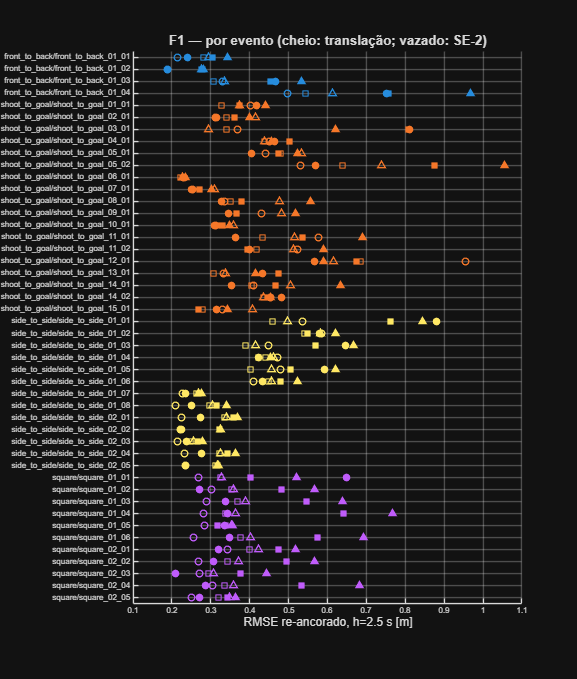

replot_f1(Tc(okc,:));                 % F1 a partir dos dados

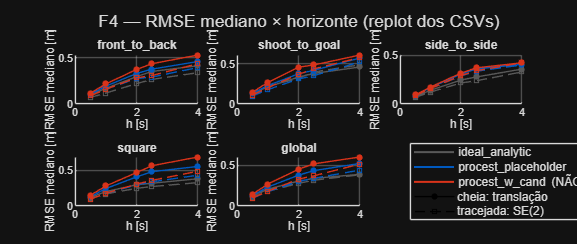

replot_f4(Mh);                        % F4 a partir dos dados

% Erro relativo à distância percorrida em h=2.5 s (truth re-amostrado a 10 Hz
% p/ não inflar o comprimento com ruído de visão):
evs = unique({traj.event});
d25 = nan(numel(evs), 1);
for i = 1:numel(evs)
    tri = traj(find(strcmp({traj.event}, evs{i}), 1));
    tg = (tri.t(1):0.1:tri.t(end))';
    xr = interp1(tri.t, tri.x_truth, tg);  yr = interp1(tri.t, tri.y_truth, tg);
    d25(i) = 2.5 * sum(hypot(diff(xr), diff(yr))) / (tg(end) - tg(1));
end
g25 = Mg(Mg.horizonte_s == 2.5, :);
pct = 100 * [min(g25.median_rmse_se2_m(1:2)) max(g25.median_rmse_trans_m(1:2))] ...
    / median(d25);
fprintf(['TAKEAWAY 7: ~0.10 m @ 0.5 s e 0.32–0.34 m @ 2.5 s — i.e. %.0f–%.0f%% ' ...
    'da distância mediana percorrida na janela (%.2f m). Sob SE(2) em h≤1 s ' ...
    'os procest empatam/superam o ideal; em shoot_to_goal SE(2) o placeholder ' ...
    'vence o ideal (0.359 vs 0.406 m).\n'], pct(1), pct(2), median(d25));

TAKEAWAY 7: ~0.10 m @ 0.5 s e 0.32–0.34 m @ 2.5 s — i.e. 12–16% da distância mediana percorrida na janela (2.65 m). Sob SE(2) em h≤1 s os procest empatam/superam o ideal; em shoot_to_goal SE(2) o placeholder vence o ideal (0.359 vs 0.406 m).


## 8. O achado — replay open-loop herda o heading da malha fechada

Os comandos do log vêm de um controlador em malha FECHADA: cada amostra já embute correções contra perturbações daquele instante. Em replay open-loop as correções "sobram" e viram deriva — dominada pelo heading, porque θ(t) errado gira os comandos de corpo e o erro de posição cresce com a distância. O teste H-a quantificou (eval 6 eventos, 2026-06-11):

pen_tr  = median(pre6.rmse_trans_m(strcmp(pre6.theta,'procest_w_cand'))) - ...
          median(pre6.rmse_trans_m(strcmp(pre6.theta,'procest_placeholder')));
pen_se2 = median(pre6.rmse_se2_m(strcmp(pre6.theta,'procest_w_cand'))) - ...
          median(pre6.rmse_se2_m(strcmp(pre6.theta,'procest_placeholder')));
fprintf(['Penalidade do candidato ω vs placeholder: +%.3f m (translação) vs ' ...
    '+%.3f m (SE-2) → %.0f%% da penalidade era heading acumulado herdado ' ...
    'pela âncora, não dinâmica.\n'], pen_tr, pen_se2, 100*(pen_tr-pen_se2)/pen_tr);

Penalidade do candidato ω vs placeholder: +0.108 m (translação) vs +0.014 m (SE-2) → 87% da penalidade era heading acumulado herdado pela âncora, não dinâmica.


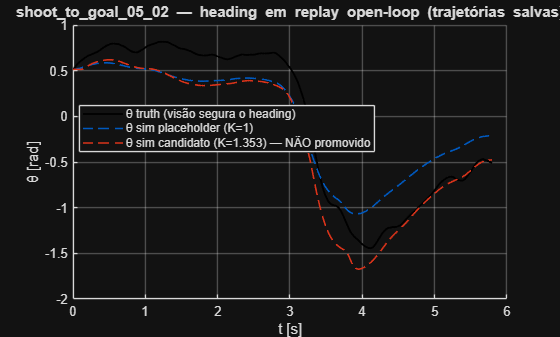

% θ(t) das trajetórias salvas: o candidato (K=1.353) amplifica a deriva.
tr8p = traj(strcmp({traj.event},'shoot_to_goal_05_02') & strcmp({traj.theta},'procest_placeholder'));
tr8c = traj(strcmp({traj.event},'shoot_to_goal_05_02') & strcmp({traj.theta},'procest_w_cand'));
figure('Name','S8 deriva de heading');
hold on; grid on;
plot(tr8p.t, tr8p.th_truth, 'k-', 'LineWidth', 1.4);
plot(tr8p.t, tr8p.th_sim, '--', 'Color', [0 .35 .75], 'LineWidth', 1.2);
plot(tr8c.t, tr8c.th_sim, '--', 'Color', [.85 .2 .1], 'LineWidth', 1.2);
legend({'θ truth (visão segura o heading)', 'θ sim placeholder (K=1)', ...
    'θ sim candidato (K=1.353) — NÃO promovido'}, 'Location', 'best');
xlabel('t [s]'); ylabel('θ [rad]');
title('shoot\_to\_goal\_05\_02 — heading em replay open-loop (trajetórias salvas)');

fprintf(['TAKEAWAY 8: NÃO é bug (seção 4: cadeia reconciliada em mm) — é o ' ...
    'fenômeno replay open-loop × malha fechada. Um K_w mais "fiel" ao dado ' ...
    'de malha fechada PIORA posição: por isso o candidato não foi promovido ' ...
    'e a coleta dedicada de ω entrou na fila.\n']);

TAKEAWAY 8: NÃO é bug (seção 4: cadeia reconciliada em mm) — é o fenômeno replay open-loop × malha fechada. Um K_w mais "fiel" ao dado de malha fechada PIORA posição: por isso o candidato não foi promovido e a coleta dedicada de ω entrou na fila.


## 9. Contribuição até aqui e próximos passos

JÁ É REAL (defensável na qualificação): • simulador verificado por reconciliação analítica (mm) — seção 4; • métrica formalizada: janelas por tempo + dupla âncora (translação e SE-2 com θ filtrado) — generalizável a qualquer gêmeo free-run; • limites caracterizados: grade irregular, excitação escassa de ω (~16 s úteis), teto de fit por ruído de pose-only — seções 2 e 6; • Td_w ≈ 106 ms recuperado dos dados (latência física); • resultado negativo documentado: ID direta de ω em malha fechada produz K_w viesado que piora posição (candidato NÃO promovido). PENDENTE: a curva que falta na F4 é a do bayesopt sobre os 9 parâmetros — bloqueada até resolver ω (garbage in, garbage out no custo de posição).

T_plano = table( ...
    {'15–19/06'; '22/06–03/07'; '06–17/07'; '20–31/07'}, ...
    {'coleta dedicada ω (chirp/degraus, malha aberta) + re-ID com hold-out'; ...
     'bayesopt 9 parâmetros, custo multi-horizonte com as DUAS métricas'; ...
     'validação cruzada entre labels + sensibilidade por DOF'; ...
     'escrita da qualificação (métrica + defeitos + campanha como espinha)'}, ...
    'VariableNames', {'janela','entrega'});
disp(T_plano)

        janela                                         entrega                                 
    _______________    ________________________________________________________________________

    {'15–19/06'   }    {'coleta dedicada ω (chirp/degraus, malha aberta) + re-ID com hold-out'}
    {'22/06–03/07'}    {'bayesopt 9 parâmetros, custo multi-horizonte com as DUAS métricas'   }
    {'06–17/07'   }    {'validação cruzada entre labels + sensibilidade por DOF'              }
    {'20–31/07'   }    {'escrita da qualificação (métrica + defeitos + campanha como espinha)'}



fprintf(['DECISÃO pedida hoje: A/B do escopo RL (CLAUDE.md: aguarda ' ...
    'orientadora; fora do escopo até a qualificação salvo ordem explícita).\n']);

DECISÃO pedida hoje: A/B do escopo RL (CLAUDE.md: aguarda orientadora; fora do escopo até a qualificação salvo ordem explícita).


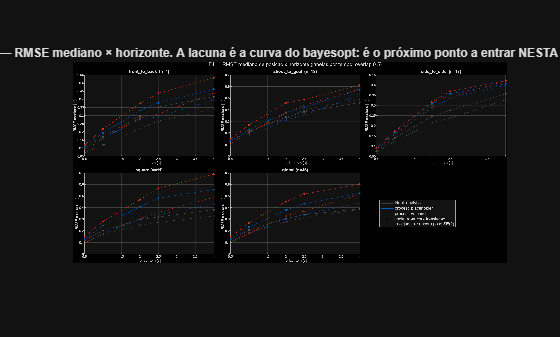

embed_png(art.png_f4, ['F4 — RMSE mediano × horizonte. A lacuna é a curva ' ...
    'do bayesopt: é o próximo ponto a entrar NESTA figura.']);

fprintf('\nTempo total do roteiro: %.1f s (RERUN=false — só artefatos).\n', toc(t_roteiro));


Tempo total do roteiro: 6.0 s (RERUN=false — só artefatos).


## ------------------------------------------------------------------------

Funções locais (resolução de artefatos, embed de PNG, demos)

function art = resolve_artefatos(repo)
% Resolve SEMPRE o timestamp mais recente de cada artefato; erra listando
% todos os ausentes de uma vez (regra: nunca recalcular silenciosamente).
R = fullfile(repo, 'results');
spec = { % campo, pasta, padrão, pegar ('last'|'first')
 'camp_csv',     R,                      'eval_campaign_2*.csv',              'last'
 'horiz_csv',    R,                      'eval_horizons_2*.csv',              'last'
 'horiz_med_csv',R,                      'eval_horizons_medianas_*.csv',      'last'
 'traj_mat',     R,                      'traj_eval_campaign_*.mat',          'last'
 'grid_csv',     R,                      'grid_audit_*.csv',                  'last'
 'exc_csv',      R,                      'check_excitation_*.csv',            'last'
 'pre_csv',      R,                      'eval_theta_full_se2_*.csv',         'first'
 'pos_csv',      R,                      'eval_theta_full_se2_*.csv',         'last'
 'tm_pre_csv',   R,                      'tabela_mestra_20260611_0728.csv',   'last'
 'tm_pos_csv',   R,                      'tabela_mestra_20260611_0852.csv',   'last'
 'ini_mat',      R,                      'sysid_initial.mat',                 'last'
 'cand_mat',     fullfile(repo,'models'),'sysid_initial_v2_candidate.mat',    'last'
 'png_grid',     fullfile(R,'figs'),     'grid_audit_dT_hist_*.png',          'last'
 'png_f1',       fullfile(R,'figs'),     'F1_dotplot_*.png',                  'last'
 'png_f3',       fullfile(R,'figs'),     'F3_compare_omega_*.png',            'last'
 'png_f4',       fullfile(R,'figs'),     'F4_horizons_*.png',                 'last'
 'png_dz',       fullfile(R,'debug'),    'cmd_vw_deadzone_square_01_01.png',  'last'
 'png_ov_antes', fullfile(R,'debug'),    'overlay_square_01_01_procest_20260611_0731.png', 'last'
 'png_ov_depois',fullfile(R,'debug'),    'overlay_square_01_01_procest_20260611_0853.png', 'last'
 };
art = struct(); faltam = {};
for i = 1:size(spec, 1)
    d = dir(fullfile(spec{i,2}, spec{i,3}));
    d = d(~[d.isdir]);
    % exclui 'medianas' quando o padrão é o CSV por evento
    if strcmp(spec{i,1}, 'camp_csv') || strcmp(spec{i,1}, 'horiz_csv')
        d = d(~contains({d.name}, 'medianas'));
    end
    if isempty(d)
        faltam{end+1} = fullfile(spec{i,2}, spec{i,3}); %#ok<AGROW>
        continue
    end
    [~, si] = sort({d.name});  d = d(si);
    if strcmp(spec{i,4}, 'first'), pick = d(1); else, pick = d(end); end
    art.(spec{i,1}) = fullfile(pick.folder, pick.name);
end
if ~isempty(faltam)
    error('Artefatos ausentes (gere-os antes; NUNCA recalcular aqui):\n  %s', ...
        strjoin(faltam, sprintf('\n  ')));
end
end

function embed_png(png_path, titulo)
% Embarca um PNG versionado como figura (sem recomputar nada).
img = imread(png_path);
figure('Name', titulo);
image(img); axis image off;
title(titulo, 'Interpreter', 'none', 'FontSize', 9);
end

function demo_duas_ancoras(tr, h, ov)
% Visualização das duas re-âncoras na MESMA trajetória salva: cada janela é
% re-ancorada no truth (esq: só translação; dir: pose SE-2 com θ truth
% filtrado, movmedian 0.2 s) e plotada sobre o caminho real.
t = tr.t;
t0s = t(1):h*(1-ov):(t(end) - h);
if isempty(t0s), t0s = t(1); end
tht_f = smoothdata(tr.th_truth, 'movmedian', 0.2, 'SamplePoints', t);
figure('Name', 'S3 demo das duas âncoras', 'Position', [80 80 1100 450]);
tl = tiledlayout(1, 2, 'TileSpacing', 'compact');
modos = {'âncora: translação', 'âncora: pose SE(2), θ filtrado'};
cores = lines(numel(t0s));
for modo = 1:2
    ax = nexttile(tl); hold(ax, 'on'); axis(ax, 'equal'); grid(ax, 'on');
    plot(ax, tr.x_truth, tr.y_truth, 'k-', 'LineWidth', 1.5);
    for j = 1:numel(t0s)
        idx = find(t >= t0s(j) & t <= t0s(j) + h);
        if numel(idx) < 2, continue; end
        i0 = idx(1);
        if modo == 1
            xa = tr.x_sim(idx) - tr.x_sim(i0) + tr.x_truth(i0);
            ya = tr.y_sim(idx) - tr.y_sim(i0) + tr.y_truth(i0);
        else
            dth = tht_f(i0) - tr.th_sim(i0);
            c = cos(dth); sn = sin(dth);
            xa = c*(tr.x_sim(idx) - tr.x_sim(i0)) - sn*(tr.y_sim(idx) - tr.y_sim(i0)) + tr.x_truth(i0);
            ya = sn*(tr.x_sim(idx) - tr.x_sim(i0)) + c*(tr.y_sim(idx) - tr.y_sim(i0)) + tr.y_truth(i0);
        end
        plot(ax, xa, ya, '--', 'Color', cores(j,:), 'LineWidth', 1.1);
        plot(ax, tr.x_truth(i0), tr.y_truth(i0), 'o', 'Color', cores(j,:), ...
            'MarkerFaceColor', cores(j,:), 'MarkerSize', 4);
    end
    title(ax, sprintf('%s — %s', strrep(tr.event, '_', '\_'), modos{modo}));
    xlabel(ax, 'x [m]'); ylabel(ax, 'y [m]');
end
title(tl, sprintf('Janelas re-ancoradas (h=%.1f s, overlap %.1f) — %s', ...
    h, ov, strrep(tr.theta, '_', '\_')));
end

function replot_f1(T)
% F1 replotada dos dados da campanha (cores=label, forma=θ, cheio=trans,
% vazado=SE-2) — mesma semântica de automation/fig_f1_dotplot.
[ev_list, ~, iev] = unique(strcat(T.label, '/', T.event), 'stable');
labels = unique(T.label, 'stable');  cols = lines(numel(labels));
thetas = {'ideal_analytic','procest_placeholder','procest_w_cand'};
marks = {'o','s','^'};
figure('Name', 'S7 F1 (replot)', 'Position', [60 40 850 1000]);
ax = axes; hold(ax, 'on');
for i = 1:height(T)
    ci = cols(strcmp(labels, T.label{i}), :);
    mk = marks{strcmp(thetas, T.theta{i})};
    plot(ax, T.rmse_trans_m(i), iev(i), mk, 'MarkerEdgeColor', ci, ...
        'MarkerFaceColor', ci, 'MarkerSize', 5);
    plot(ax, T.rmse_se2_m(i), iev(i), mk, 'MarkerEdgeColor', ci, ...
        'MarkerFaceColor', 'none', 'MarkerSize', 5, 'LineWidth', 1);
end
set(ax, 'YTick', 1:numel(ev_list), 'YTickLabel', strrep(ev_list, '_', '\_'), ...
    'YDir', 'reverse', 'FontSize', 6);
ylim(ax, [0.5 numel(ev_list) + 0.5]); grid(ax, 'on');
xlabel(ax, 'RMSE re-ancorado, h=2.5 s [m]', 'FontSize', 9);
title(ax, 'F1 — por evento (cheio: translação; vazado: SE-2)', 'FontSize', 10);
end

function replot_f4(Mh)
% F4 replotada do CSV de medianas multi-horizonte (painel por label+global).
panels = [setdiff(unique(Mh.label), {'global'}); {'global'}];
thetas = {'ideal_analytic','procest_placeholder','procest_w_cand'};
cols = [.35 .35 .35; 0 .35 .75; .85 .2 .1];
figure('Name', 'S7 F4 (replot)', 'Position', [80 60 1300 550]);
tl = tiledlayout(2, 3, 'TileSpacing', 'compact');
for p = 1:numel(panels)
    ax = nexttile(tl); hold(ax, 'on'); grid(ax, 'on');
    for k = 1:numel(thetas)
        sub = sortrows(Mh(strcmp(Mh.label, panels{p}) & ...
            strcmp(Mh.theta, thetas{k}), :), 'horizonte_s');
        plot(ax, sub.horizonte_s, sub.median_rmse_trans_m, '-o', ...
            'Color', cols(k,:), 'MarkerFaceColor', cols(k,:), 'MarkerSize', 4);
        plot(ax, sub.horizonte_s, sub.median_rmse_se2_m, '--s', ...
            'Color', cols(k,:), 'MarkerSize', 4);
    end
    title(ax, strrep(panels{p}, '_', '\_'), 'FontSize', 9);
    xlabel(ax, 'h [s]'); ylabel(ax, 'RMSE mediano [m]');
end
ax = nexttile(tl); axis(ax, 'off'); hold(ax, 'on');
hh = [plot(ax, NaN, NaN, '-', 'Color', cols(1,:), 'LineWidth', 1.5), ...
      plot(ax, NaN, NaN, '-', 'Color', cols(2,:), 'LineWidth', 1.5), ...
      plot(ax, NaN, NaN, '-', 'Color', cols(3,:), 'LineWidth', 1.5), ...
      plot(ax, NaN, NaN, '-ok', 'MarkerFaceColor', 'k', 'MarkerSize', 4), ...
      plot(ax, NaN, NaN, '--sk', 'MarkerSize', 4)];
legend(ax, hh, {'ideal\_analytic', 'procest\_placeholder', ...
    'procest\_w\_cand (NÃO promovido)', 'cheia: translação', ...
    'tracejada: SE(2)'}, 'Location', 'west', 'FontSize', 9);
title(tl, 'F4 — RMSE mediano × horizonte (replot dos CSVs)');
end